# Ultrasonic Signal Analysis for Crack Detection in Steel Using Digital Signal Processing 

 ELEC5305 Acoustics, Speech and Signal Processing 

Lab Report 1

Author: Karthik Ramesh

SID: 550754365

Date: 02-09-2026

### **1. Objective**

The objective of this report is to investigate how fundamental digital signal processing techniques can be applied to ultrasonic non-destructive testing of steel. Experimental Full Matrix Capture (FMC) data containing a known centreline crack are analysed using time-domain inspection, band-pass filtering, envelope detection, frequency-domain analysis and Short-Time Fourier Transform (STFT) methods. A controlled synthetic ultrasonic pulse-echo model is also developed to examine how a crack-induced reflection affects signal characteristics and extracted features.

### **2. Background**

Ultrasonic non-destructive testing (NDT) is widely used to inspect engineering materials because internal discontinuities such as cracks can reflect acoustic energy without damaging the component. In phased-array inspection, Full Matrix Capture (FMC) records the time-domain response for every transmit–receive element combination, providing a rich dataset for subsequent signal processing and localisation. 

The measured ultrasonic response can be examined in both the time and frequency domains. Time-domain analysis is useful for studying the arrival and magnitude of reflected pulses, while Fourier analysis **[1]** reveals the frequency content of the received signal. Band-pass filtering can isolate the operating frequency range of the ultrasonic transducer, and envelope detection provides a clearer representation of transient echo magnitude. For signals whose spectral content changes with time, the Short-Time Fourier Transform (STFT) provides a joint time-frequency representation and introduces a trade-off between temporal and frequency resolution.

 These deterministic DSP techniques provide an interpretable foundation for ultrasonic flaw analysis before more advanced localisation or machine-learning methods are introduced.

### **3. Methodology and Implementation**

The analysis was implemented in MATLAB using experimental Full Matrix Capture (FMC) ultrasonic data from the University of Strathclyde. The dataset contains 10,000 temporal samples for each of 45 transmitting and 45 receiving array elements. According to the accompanying metadata, the sampling frequency is 100 MHz, the array centre frequency is 5 MHz, the element pitch is 0.7 mm, and the estimated ultrasonic propagation velocity is 5780 m/s. The inspected specimen contains a 12 mm centreline crack located approximately 37 mm below the inspection surface.

A representative pulse-echo A-scan was first extracted and converted from sample index to physical time. Approximate crack and back-wall arrival times were estimated using the pulse-echo relation  . The measured signal was then band-pass filtered between 3.5 and 6.5 MHz using zero-phase filtering, followed by Hilbert-transform envelope detection. Frequency-domain characteristics were examined using a Hann-windowed FFT **[2]**.

To provide a controlled comparison, a synthetic five-cycle 5 MHz ultrasonic pulse was generated and delayed copies were added to represent crack and back-wall reflections. RMS amplitude, signal energy, peak envelope and spectral centroid were then extracted. Finally, STFT analysis compared 0.5 µs and 2.0 µs Hann windows to demonstrate the time-frequency resolution trade-off.

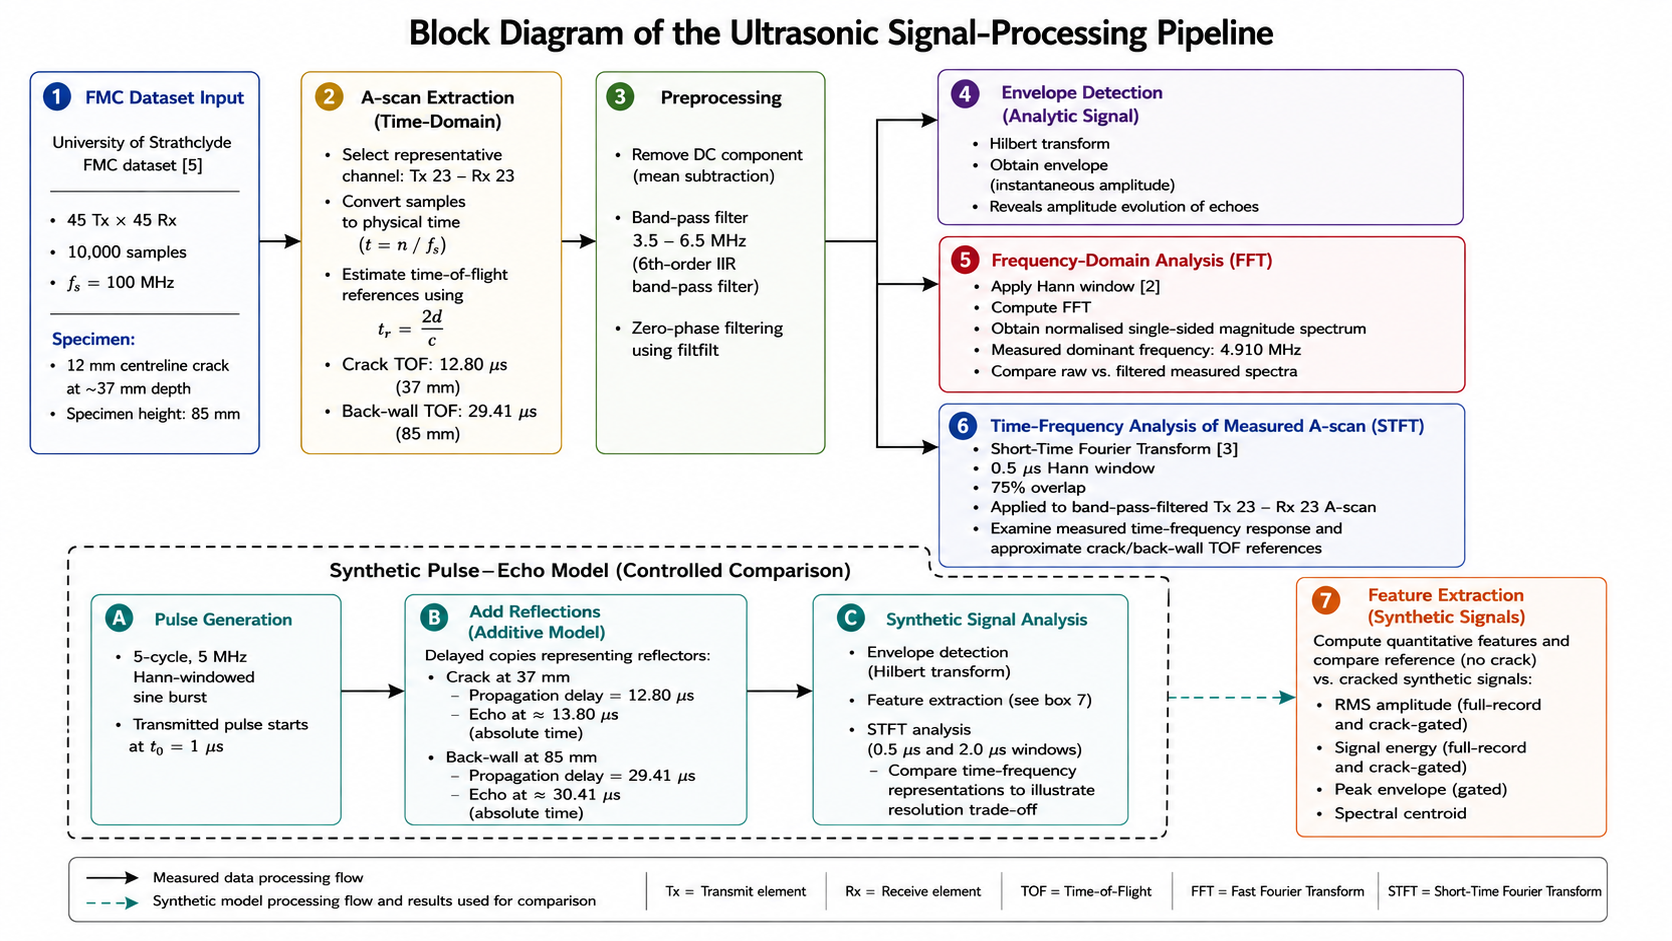

### **4. Code and Results**

The following sections apply the processing pipeline described above to the experimental FMC dataset and to a controlled synthetic ultrasonic signal. Each processing stage is accompanied by numerical or graphical results to demonstrate its effect on the ultrasonic response.

### 4.1 FMC Dataset Preparation and Time-Domain Analysis

The experimental FMC data **[5]** were loaded into MATLAB as a three-dimensional array containing 10,000 temporal samples for each of the   transmit–receive combinations. The supplied acquisition parameters were then used to construct a physical time axis. At the 100 MHz sampling frequency, each sample represents 10 ns, while the nominal 5 MHz ultrasonic carrier is represented by approximately 20 samples per cycle.


%% 4.1 Load and Prepare FMC Dataset

clear;
clc;
close all;

% Load ultrasonic Full Matrix Capture data
S = load('FMC_2012_04_26_at_16_16.mat');
FMC = double(S.FMC_new);

% Experimental parameters from supplied metadata
fs = 100e6;              % Sampling frequency [Hz]
fc = 5e6;                % Transducer centre frequency [Hz]
cSteel = 5780;           % Estimated wave velocity [m/s]
arrayPitch = 0.7e-3;     % Array element pitch [m]

crackDepth = 37e-3;      % Known crack depth [m]
sampleDepth = 85e-3;     % Specimen height [m]

% Dataset dimensions
[nSamples, nTx, nRx] = size(FMC);

% Physical time axis
t = (0:nSamples-1).' / fs;
t_us = t * 1e6;

fprintf('Dataset dimensions: %d samples × %d Tx × %d Rx\n', ...
    nSamples, nTx, nRx);

Dataset dimensions: 10000 samples × 45 Tx × 45 Rx



fprintf('Sampling frequency: %.1f MHz\n', fs/1e6);

Sampling frequency: 100.0 MHz


fprintf('Transducer centre frequency: %.1f MHz\n', fc/1e6);

Transducer centre frequency: 5.0 MHz


### 4.1.1 Time-of-Flight Reference

Approximate reflector locations were calculated using the pulse-echo time-of-flight relationship

where  is the reflector depth and  is the assumed ultrasonic propagation velocity. Using  m/s gives an approximate crack arrival time of 12.80 µs for the known 37 mm flaw and a back-wall arrival time of 29.41 µs for the 85 mm specimen depth. These values are used only as straight-path reference locations because propagation through the weld can be more complex.

%% 4.1.1 Approximate Time-of-Flight References

tCrack = 2 * crackDepth / cSteel;
tBackwall = 2 * sampleDepth / cSteel;

fprintf('Approximate crack echo time: %.2f us\n', ...
    tCrack*1e6);

Approximate crack echo time: 12.80 us



fprintf('Approximate back-wall echo time: %.2f us\n', ...
    tBackwall*1e6);

Approximate back-wall echo time: 29.41 us


### 4.1.2 Representative A-scan

A central pulse-echo channel, Tx 23–Rx 23, was selected as a representative A-scan for the initial analysis. The calculated crack and back-wall times were superimposed on the waveform to provide physical reference points.

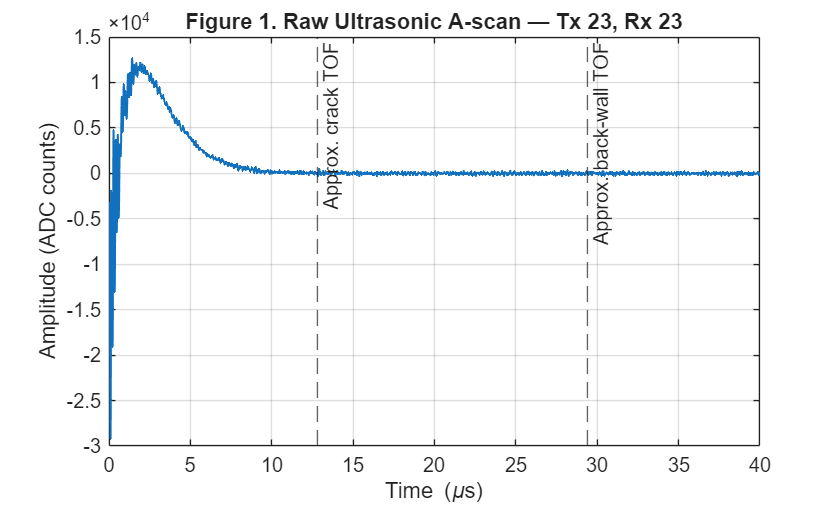

%% 4.1.2 Representative Raw A-scan

tx = 23;
rx = 23;

xRaw = squeeze(FMC(:,tx,rx));

figure;
plot(t_us, xRaw, 'LineWidth', 1);

hold on;

xline(tCrack*1e6, '--', 'Approx. crack TOF');
xline(tBackwall*1e6, '--', 'Approx. back-wall TOF');

xlabel('Time (\mus)');
ylabel('Amplitude (ADC counts)');

title(sprintf('Figure 1. Raw Ultrasonic A-scan — Tx %d, Rx %d', tx, rx));

xlim([0 40]);
grid on;

Figure 1 shows that the raw measurement is dominated by a large initial transient followed by a rapidly decaying response. Later reflected components are comparatively small on the linear amplitude scale and cannot be confidently identified from the unprocessed waveform alone. In particular, no isolated reflection can be assigned unambiguously to the 12.80 µs crack reference from this single raw A-scan. This motivates frequency-selective filtering and envelope processing in the following section.

### 4.2 Band-Pass Filtering and Envelope Detection

The raw A-scan contains a strong transient component that dominates the measured response and makes weaker ultrasonic reflections difficult to interpret. Since the transducer has a nominal centre frequency of 5 MHz, a band-pass filter from 3.5 to 6.5 MHz was applied to retain the dominant ultrasonic frequency range while suppressing out-of-band components. Zero-phase filtering using filtfilt was used to avoid introducing additional phase delay into the measured waveform. The magnitude of the analytic signal was then calculated using the Hilbert transform to obtain the signal envelope. 

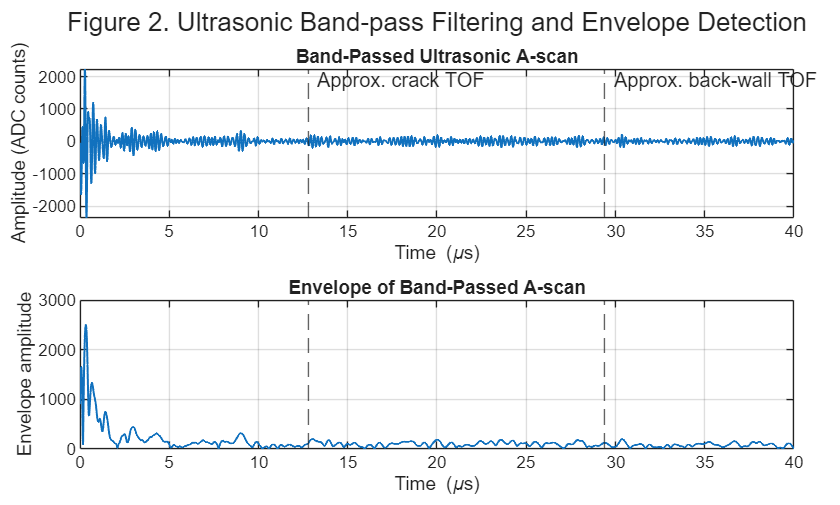


%% 4.2 Band-pass Filtering and Envelope Detection

% Approximate useful bandwidth around the 5 MHz transducer
fLow = 3.5e6;
fHigh = 6.5e6;

% Remove DC component
x = xRaw - mean(xRaw);

% Design band-pass filter
bpFilt = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', fLow, ...
    'HalfPowerFrequency2', fHigh, ...
    'SampleRate', fs);

% Zero-phase filtering
xFilt = filtfilt(bpFilt, x);

% Analytic-signal envelope
xEnv = abs(hilbert(xFilt));

% Plot comparison
figure;

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

nexttile;
plot(t_us, xFilt, 'LineWidth', 1);
hold on;

xline(tCrack*1e6, '--');
xline(tBackwall*1e6, '--');

text(tCrack*1e6 + 0.5, 0.85*max(xFilt), ...
    'Approx. crack TOF');

text(tBackwall*1e6 + 0.5, 0.85*max(xFilt), ...
    'Approx. back-wall TOF');

xlabel('Time (\mus)');
ylabel('Amplitude (ADC counts)');
title('Band-Passed Ultrasonic A-scan');
xlim([0 40]);
grid on;

nexttile;
plot(t_us, xEnv, 'LineWidth', 1);
hold on;

xline(tCrack*1e6, '--');
xline(tBackwall*1e6, '--');

xlabel('Time (\mus)');
ylabel('Envelope amplitude');
title('Envelope of Band-Passed A-scan');
xlim([0 40]);
grid on;

sgtitle('Figure 2. Ultrasonic Band-pass Filtering and Envelope Detection');

e[n]=∣  +j ∣

where  is the band-pass-filtered signal and  denotes the Hilbert transform.

Figure 2 shows that band-pass filtering removes much of the slowly varying content present in the raw A-scan and preserves the oscillatory ultrasonic response around the transducer operating band. The filtered waveform still contains a strong initial response, but later ultrasonic components are more visible than in Figure 1. Envelope detection further simplifies interpretation by removing the rapid carrier oscillation and representing the instantaneous magnitude of the ultrasonic signal. This provides a clearer indication of reflected pulse energy, although no single isolated peak at the approximate crack time can yet be assigned unambiguously to the flaw from this channel alone.

### 4.3 Frequency-Domain Analysis Using the FFT

The frequency content of the ultrasonic A-scan was analysed using the Fast Fourier Transform (FFT). A Hann window was applied before transformation to reduce spectral leakage caused by analysing a finite-duration signal. Both the raw and band-pass-filtered A-scans were converted to normalised single-sided magnitude spectra so that their spectral shapes could be compared. Since the ultrasonic transducer has a nominal centre frequency of 5 MHz, the filtered response was expected to contain its strongest spectral energy close to this frequency.

 

where   is the sampled ultrasonic signal and   is its discrete frequency-domain representation.

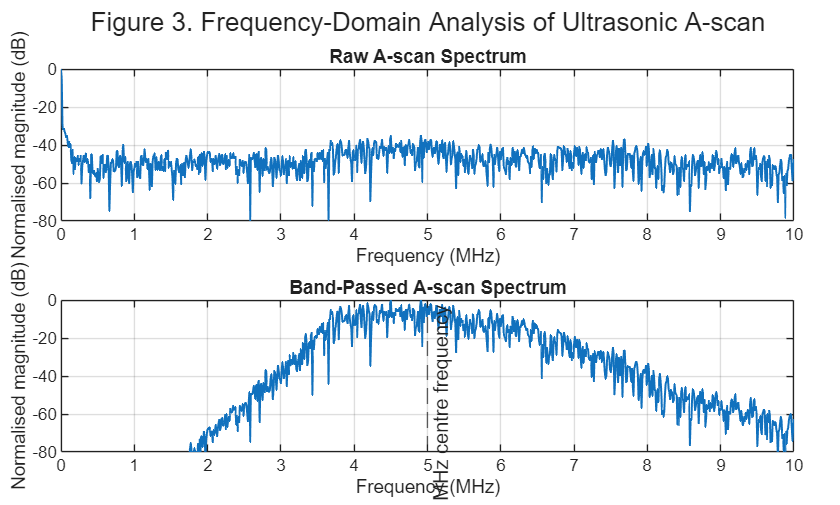

%% 4.3 Frequency-Domain Analysis

N = length(x);

% Hann window to reduce spectral leakage
w = hann(N);

% Window raw and filtered signals
xRawWindowed = x .* w;
xFiltWindowed = xFilt .* w;

% FFT
Xraw = fft(xRawWindowed);
Xfilt = fft(xFiltWindowed);

% Single-sided spectrum
nHalf = floor(N/2) + 1;

Xraw = abs(Xraw(1:nHalf));
Xfilt = abs(Xfilt(1:nHalf));

% Frequency axis
f = (0:nHalf-1).' * fs / N;
f_MHz = f / 1e6;

% Normalise each spectrum for comparison
Xraw_dB = 20*log10(Xraw / max(Xraw) + eps);
Xfilt_dB = 20*log10(Xfilt / max(Xfilt) + eps);

% Plot
figure;

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

nexttile;
plot(f_MHz, Xraw_dB, 'LineWidth', 1);

xlabel('Frequency (MHz)');
ylabel('Normalised magnitude (dB)');
title('Raw A-scan Spectrum');

xlim([0 10]);
ylim([-80 0]);
grid on;

nexttile;
plot(f_MHz, Xfilt_dB, 'LineWidth', 1);

hold on;
xline(fc/1e6, '--', '5 MHz centre frequency');

xlabel('Frequency (MHz)');
ylabel('Normalised magnitude (dB)');
title('Band-Passed A-scan Spectrum');

xlim([0 10]);
ylim([-80 0]);
grid on;

sgtitle('Figure 3. Frequency-Domain Analysis of Ultrasonic A-scan');


%% Dominant Frequency

[~, peakIndex] = max(Xfilt);

dominantFrequency = f(peakIndex);

fprintf('Dominant filtered frequency: %.3f MHz\n', ...
    dominantFrequency/1e6);

Dominant filtered frequency: 4.910 MHz


Figure 3 shows that the raw A-scan contains broadband spectral content, whereas the filtered response is concentrated around the operating range of the ultrasonic transducer. The dominant frequency of the filtered signal was measured as **4.910 MHz**, which is close to the nominal 5 MHz centre frequency. This confirms that the 3.5–6.5 MHz band-pass filter retained the principal ultrasonic component while suppressing frequencies outside the intended analysis band. Because the two spectra were normalised independently, the comparison illustrates differences in spectral shape rather than absolute signal attenuation.

### 4.4 Synthetic Ultrasonic Pulse-Echo Model

To complement the experimental data with a controlled example, a synthetic ultrasonic pulse-echo signal was generated using a five-cycle 5 MHz sinusoidal burst shaped by a Hann window. Two cases were constructed: a reference specimen containing the transmitted pulse and a back-wall reflection, and a cracked specimen containing an additional attenuated reflection at the theoretical crack time of flight. This controlled model makes the effect of an internal reflector easier to interpret than in the measured FMC signal, where scattering and noise are present.

The transmitted pulse model:

and the received signal model:

where  and  represent the illustrative crack and back-wall reflection amplitudes.

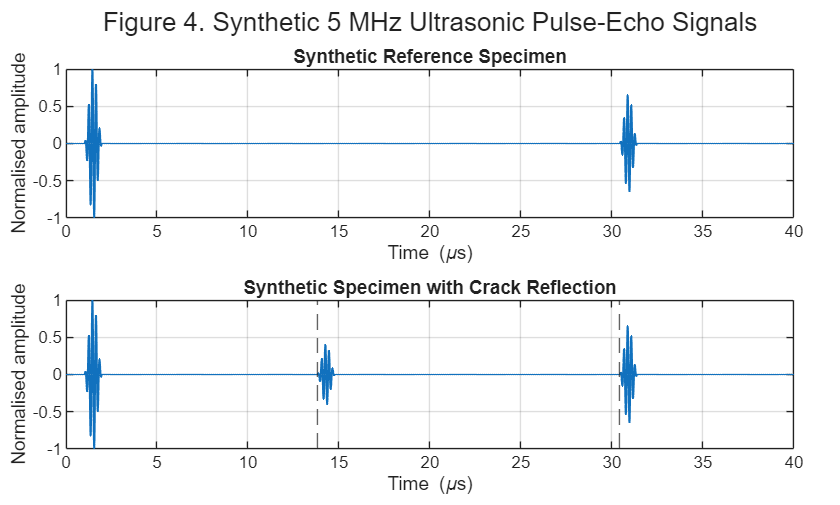

%% 4.4 Synthetic Ultrasonic Pulse and Crack Echo

% Synthetic record duration
syntheticDuration = 40e-6;

nSynthetic = round(syntheticDuration * fs);
tSynthetic = (0:nSynthetic-1).' / fs;
tSynthetic_us = tSynthetic * 1e6;

% Create a 5-cycle ultrasonic burst
nCycles = 5;
nPulse = round(nCycles * fs / fc);

n = (0:nPulse-1).';

pulse = sin(2*pi*fc*n/fs) .* hann(nPulse);

% Normalise pulse
pulse = pulse / max(abs(pulse));

% Initial transmitted pulse position
t0 = 1e-6;

% Echo arrival locations
tCrackSynthetic = t0 + tCrack;
tBackSynthetic = t0 + tBackwall;

idxDirect = round(t0 * fs) + 1;
idxCrack  = round(tCrackSynthetic * fs) + 1;
idxBack   = round(tBackSynthetic * fs) + 1;

% Illustrative reflection amplitudes
crackAmplitude = 0.40;
backwallAmplitude = 0.65;

% Initialise signals
xReference = zeros(nSynthetic,1);
xCracked   = zeros(nSynthetic,1);

%% Reference specimen: direct pulse + back-wall echo

idx = idxDirect:(idxDirect+nPulse-1);
xReference(idx) = xReference(idx) + pulse;

idx = idxBack:(idxBack+nPulse-1);
xReference(idx) = xReference(idx) + ...
    backwallAmplitude*pulse;

%% Cracked specimen: direct pulse + crack echo + back-wall echo

idx = idxDirect:(idxDirect+nPulse-1);
xCracked(idx) = xCracked(idx) + pulse;

idx = idxCrack:(idxCrack+nPulse-1);
xCracked(idx) = xCracked(idx) + ...
    crackAmplitude*pulse;

idx = idxBack:(idxBack+nPulse-1);
xCracked(idx) = xCracked(idx) + ...
    backwallAmplitude*pulse;

%% Calculate envelopes

envReference = abs(hilbert(xReference));
envCracked   = abs(hilbert(xCracked));

%% Plot synthetic signals

figure;

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

nexttile;

plot(tSynthetic_us, xReference, ...
    'LineWidth',1);

xlabel('Time (\mus)');
ylabel('Normalised amplitude');
title('Synthetic Reference Specimen');

xlim([0 40]);
grid on;

nexttile;

plot(tSynthetic_us, xCracked, ...
    'LineWidth',1);

hold on;

xline(tCrackSynthetic*1e6, '--');
xline(tBackSynthetic*1e6, '--');

xlabel('Time (\mus)');
ylabel('Normalised amplitude');
title('Synthetic Specimen with Crack Reflection');

xlim([0 40]);
grid on;

sgtitle('Figure 4. Synthetic 5 MHz Ultrasonic Pulse-Echo Signals');

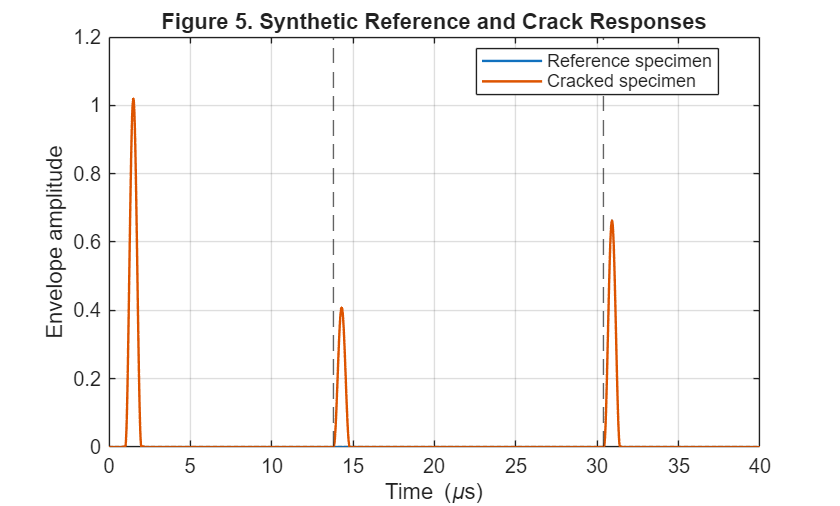


%% Synthetic Envelope Comparison

figure;

plot(tSynthetic_us, envReference, ...
    'LineWidth',1.2);

hold on;

plot(tSynthetic_us, envCracked, ...
    'LineWidth',1.2);

xline(tCrackSynthetic*1e6, '--');
xline(tBackSynthetic*1e6, '--');

xlabel('Time (\mus)');
ylabel('Envelope amplitude');

title('Figure 5. Synthetic Reference and Crack Responses');

legend('Reference specimen', ...
       'Cracked specimen', ...
       'Location','best');

xlim([0 40]);
grid on;

Figures 4 and 5 show the controlled effect of introducing an internal reflector into the ultrasonic response. Both synthetic signals contain the transmitted pulse and a delayed back-wall echo, while the cracked specimen contains an additional reflection at approximately 13.8 µs. The envelope representation makes this additional pulse particularly clear because the rapid 5 MHz carrier oscillation is removed from the visual interpretation. The synthetic model therefore demonstrates the basic pulse-echo principle of crack detection: an internal discontinuity can introduce reflected energy before the expected back-wall response. Note: - The reflection amplitudes of 0.40 for the crack and 0.65 for the back wall were selected as illustrative modelling parameters and do not represent calibrated reflection coefficients from the experimental specimen.

### 4.5 Signal Feature Extraction

Signal features were extracted from the synthetic reference and cracked signals to quantify differences that are visually apparent in the pulse-echo waveforms. The selected features were root-mean-square (RMS) amplitude, signal energy, peak envelope amplitude and spectral centroid. In addition to full-record features, a short time gate was placed around the simulated crack echo so that the localised response could be measured independently of the transmitted pulse and back-wall reflection. 

The RMS and energy equations:

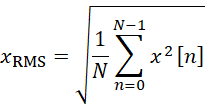

and the spectral centroid:

%% 4.5 Signal Feature Extraction

% Define a short inspection gate around the simulated crack echo
gateStart = tCrackSynthetic - 1e-6;
gateEnd   = tCrackSynthetic + 2e-6;

crackGate = ...
    (tSynthetic >= gateStart) & ...
    (tSynthetic <= gateEnd);

%% Full-record RMS and energy

rmsReference = rms(xReference);
rmsCracked   = rms(xCracked);

energyReference = sum(xReference.^2);
energyCracked   = sum(xCracked.^2);

%% Crack-gated amplitude features

peakGateReference = max(envReference(crackGate));
peakGateCracked   = max(envCracked(crackGate));

rmsGateReference = rms(xReference(crackGate));
rmsGateCracked   = rms(xCracked(crackGate));

energyGateReference = ...
    sum(xReference(crackGate).^2);

energyGateCracked = ...
    sum(xCracked(crackGate).^2);

%% Spectral centroid

Nsyn = length(xReference);

fSyn = (0:floor(Nsyn/2)).' * fs / Nsyn;

Xref = fft(xReference);
Xcrk = fft(xCracked);

Pref = abs(Xref(1:length(fSyn))).^2;
Pcrk = abs(Xcrk(1:length(fSyn))).^2;

centroidReference = ...
    sum(fSyn .* Pref) / sum(Pref);

centroidCracked = ...
    sum(fSyn .* Pcrk) / sum(Pcrk);

%% Display results

featureName = {
    'Full-record RMS'
    'Full-record energy'
    'Crack-gate peak envelope'
    'Crack-gate RMS'
    'Crack-gate energy'
    'Spectral centroid (MHz)'
};

referenceValue = [
    rmsReference
    energyReference
    peakGateReference
    rmsGateReference
    energyGateReference
    centroidReference/1e6
];

crackedValue = [
    rmsCracked
    energyCracked
    peakGateCracked
    rmsGateCracked
    energyGateCracked
    centroidCracked/1e6
];

featureTable = table( ...
    featureName, ...
    referenceValue, ...
    crackedValue, ...
    'VariableNames', ...
    {'Feature','Reference','Cracked'});

disp(featureTable);

              Feature               Reference     Cracked 
    ____________________________    __________    ________

    {'Full-record RMS'         }      0.082928    0.087468
    {'Full-record energy'      }        27.508      30.602
    {'Crack-gate peak envelope'}    2.5627e-06     0.40786
    {'Crack-gate RMS'          }             0     0.10156
    {'Crack-gate energy'       }             0      3.0941
    {'Spectral centroid (MHz)' }             5           5



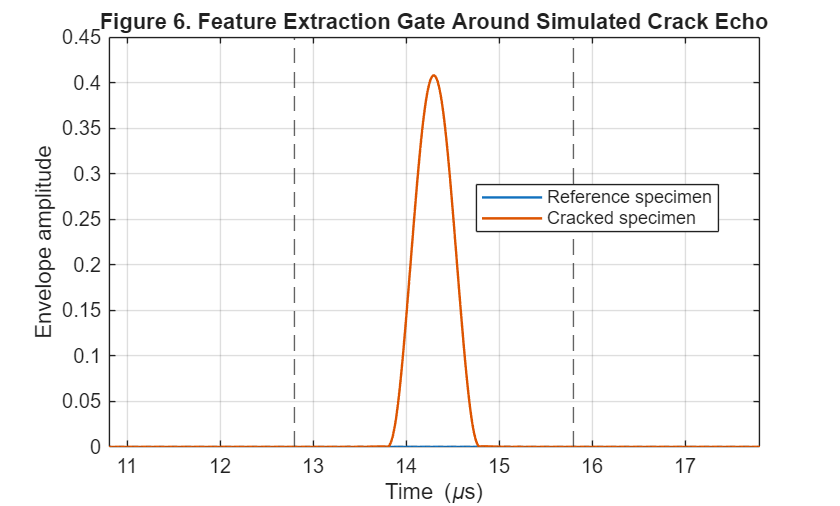


%% Crack-Gate Feature Comparison

figure;

plot(tSynthetic_us, envReference, ...
    'LineWidth',1.2);

hold on;

plot(tSynthetic_us, envCracked, ...
    'LineWidth',1.2);

xline(gateStart*1e6, '--');
xline(gateEnd*1e6, '--');

xlabel('Time (\mus)');
ylabel('Envelope amplitude');

title('Figure 6. Feature Extraction Gate Around Simulated Crack Echo');

legend('Reference specimen', ...
       'Cracked specimen', ...
       'Location','best');

xlim([(gateStart-2e-6)*1e6 ...
      (gateEnd+2e-6)*1e6]);

grid on;

The table shows that the synthetic crack produces only a modest increase in the full-record RMS and total energy because the transmitted pulse and back-wall reflection are common to both signals. In contrast, the gated features provide clear separation between the two cases. Within the crack time gate, the reference signal contains essentially no energy, while the cracked signal produces an RMS amplitude of 0.10156, a peak envelope of 0.40786 and an energy of 3.0941. The spectral centroid remains at 5 MHz for both signals, indicating that the simulated flaw changes the timing and magnitude of the returned energy rather than the carrier frequency itself. These results suggest that localised amplitude- and energy-based features are more informative for this detection task than spectral centroid alone. Note: - The very small non-zero reference peak envelope is a numerical residual from the analytic-signal calculation and is effectively zero for this comparison.

### 4.6 STFT Time-Frequency Analysis

The Fast Fourier Transform describes the overall frequency content of a signal but does not indicate when individual spectral components occur. This is a limitation for ultrasonic pulse-echo signals because the arrival time of each reflection contains information about reflector position. The Short-Time Fourier Transform (STFT) was therefore applied to the synthetic cracked signal using overlapping Hann windows **[3]**. Two window durations, 0.5 µs and 2.0 µs, were compared to demonstrate the fundamental trade-off between temporal and frequency resolution. 

The STFT expression:

where   is the analysis window and   is the hop size between adjacent frames.

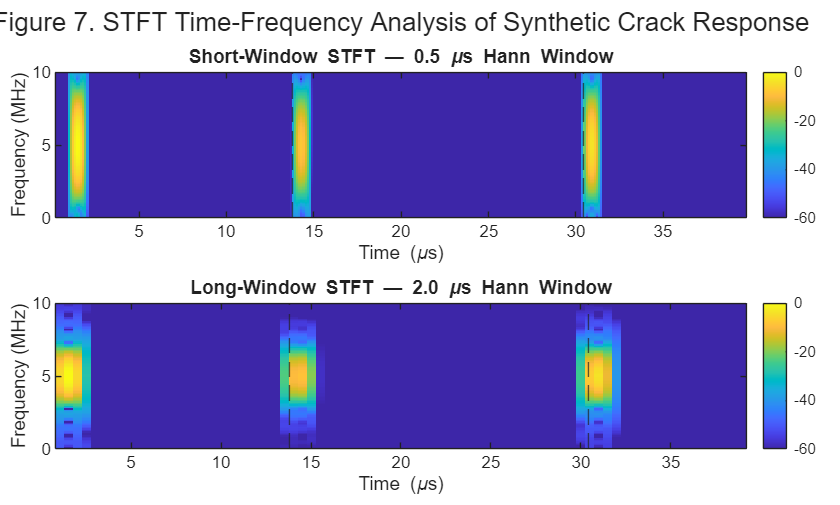

%% 4.6 Short-Time Fourier Transform Analysis

% Window durations
shortWindow_us = 0.5;
longWindow_us  = 2.0;

% Convert durations to samples
Lshort = round(shortWindow_us * 1e-6 * fs);
Llong  = round(longWindow_us  * 1e-6 * fs);

% Hann analysis windows
wShort = hann(Lshort, 'periodic');
wLong  = hann(Llong,  'periodic');

% 75% overlap
overlapShort = round(0.75 * Lshort);
overlapLong  = round(0.75 * Llong);

% FFT length
NfftSTFT = 1024;

%% Short-window STFT

[Sshort, Fshort, Tshort] = spectrogram( ...
    xCracked, ...
    wShort, ...
    overlapShort, ...
    NfftSTFT, ...
    fs);

Sshort_dB = 20*log10(abs(Sshort) + eps);
Sshort_dB = Sshort_dB - max(Sshort_dB(:));

%% Long-window STFT

[Slong, Flong, Tlong] = spectrogram( ...
    xCracked, ...
    wLong, ...
    overlapLong, ...
    NfftSTFT, ...
    fs);

Slong_dB = 20*log10(abs(Slong) + eps);
Slong_dB = Slong_dB - max(Slong_dB(:));

%% Plot comparison

figure;

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

% Short window
nexttile;

imagesc( ...
    Tshort*1e6, ...
    Fshort/1e6, ...
    Sshort_dB);

axis xy;

hold on;

xline(tCrackSynthetic*1e6, '--');
xline(tBackSynthetic*1e6, '--');

xlabel('Time (\mus)');
ylabel('Frequency (MHz)');

title(sprintf( ...
    'Short-Window STFT — %.1f \\mus Hann Window', ...
    shortWindow_us));

ylim([0 10]);
caxis([-60 0]);
colorbar;

% Long window
nexttile;

imagesc( ...
    Tlong*1e6, ...
    Flong/1e6, ...
    Slong_dB);

axis xy;

hold on;

xline(tCrackSynthetic*1e6, '--');
xline(tBackSynthetic*1e6, '--');

xlabel('Time (\mus)');
ylabel('Frequency (MHz)');

title(sprintf( ...
    'Long-Window STFT — %.1f \\mus Hann Window', ...
    longWindow_us));

ylim([0 10]);
caxis([-60 0]);
colorbar;

sgtitle('Figure 7. STFT Time-Frequency Analysis of Synthetic Crack Response');

Figure 7 shows three distinct time-frequency events corresponding to the transmitted pulse, simulated crack reflection and back-wall reflection. All three are centred close to the 5 MHz carrier frequency. With the shorter 0.5 µs window, the events are sharply localised in time but spread over a broader frequency range. In contrast, the 2.0 µs window produces stronger frequency localisation around 5 MHz at the cost of increased temporal spreading. This demonstrates the fundamental STFT time-frequency resolution trade-off. For ultrasonic crack analysis, shorter windows can be advantageous when closely spaced echoes must be distinguished in time, whereas longer windows provide a more precise estimate of the spectral content of each reflection.

### 4.7 STFT of the Measured Ultrasonic A-scan

The same STFT method was then applied to the experimentally measured, band-pass-filtered A-scan. A 0.5 µs Hann window with 75% overlap was selected to prioritise temporal localisation of transient ultrasonic events. Unlike the controlled synthetic signal, the measured response contains scattering, attenuation, structural reflections and noise, so a more complex time-frequency pattern is expected.

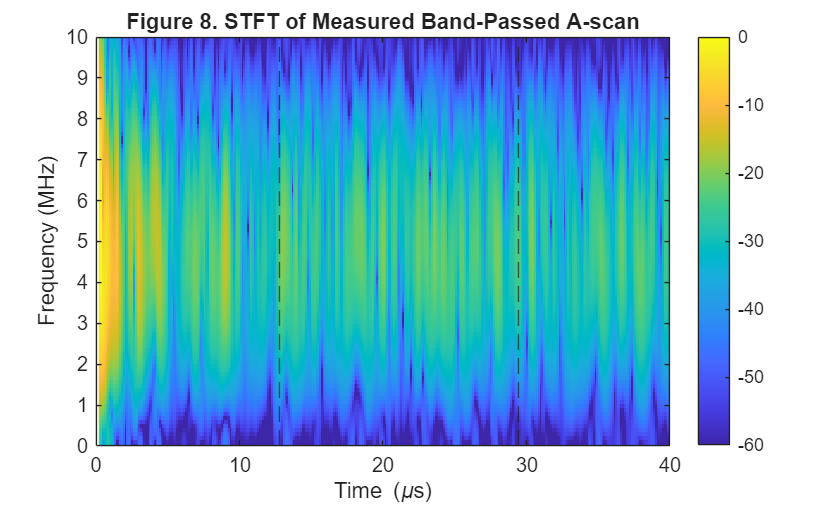

%% 4.7 STFT of Measured Ultrasonic A-scan

% Use 0.5 us Hann window for improved temporal localisation
Lmeasured = round(0.5e-6 * fs);
wMeasured = hann(Lmeasured, 'periodic');

overlapMeasured = round(0.75 * Lmeasured);
NfftMeasured = 1024;

[Smeas, Fmeas, Tmeas] = spectrogram( ...
    xFilt, ...
    wMeasured, ...
    overlapMeasured, ...
    NfftMeasured, ...
    fs);

Smeas_dB = 20*log10(abs(Smeas) + eps);
Smeas_dB = Smeas_dB - max(Smeas_dB(:));

figure;

imagesc( ...
    Tmeas*1e6, ...
    Fmeas/1e6, ...
    Smeas_dB);

axis xy;

hold on;

xline(tCrack*1e6, '--');
xline(tBackwall*1e6, '--');

xlabel('Time (\mus)');
ylabel('Frequency (MHz)');

title('Figure 8. STFT of Measured Band-Passed A-scan');

xlim([0 40]);
ylim([0 10]);

caxis([-60 0]);

colorbar;

Figure 8 shows that the measured ultrasonic response is substantially more complex than the controlled synthetic case. Energy is distributed across the ultrasonic frequency band and persists throughout the analysed time interval, with the strongest response occurring near the beginning of the record. The broad spectral appearance is also consistent with the relatively short 0.5 µs analysis window, which provides good temporal localisation at the expense of frequency resolution. Although the calculated 12.80 µs crack time is shown as a reference, no isolated time-frequency event in this single Tx 23–Rx 23 channel can be confidently attributed to the crack. This demonstrates a key limitation of single-channel pulse-echo analysis and motivates the use of information from multiple FMC transmit–receive channels for more robust flaw detection and localisation**[4]**.

### **5. Discussion**

The results demonstrate that the usefulness of ultrasonic measurements depends strongly on the signal-processing method applied. The raw experimental A-scan was dominated by a large initial transient, making later reflections difficult to interpret directly. Band-pass filtering between 3.5 and 6.5 MHz reduced out-of-band content and retained the expected transducer response, with the filtered signal exhibiting a dominant frequency of 4.910 MHz compared with the nominal 5 MHz centre frequency. Envelope detection further improved interpretation by representing reflected pulse magnitude without the rapid carrier oscillation.

The synthetic pulse-echo experiment provided a clearer demonstration of crack-related signal behaviour. Introducing an additional reflection at the expected crack arrival time caused only modest changes to full-record RMS and energy because the transmitted pulse and back-wall reflection were common to both signals. In contrast, time-gated features around the crack response produced strong separation between the reference and cracked cases. The unchanged 5 MHz spectral centroid also showed that the simulated flaw altered the timing and magnitude of reflected energy rather than the carrier frequency itself.

 The STFT experiments demonstrated the expected time-frequency resolution trade-off. The 0.5 µs window improved temporal localisation, whereas the 2.0 µs window concentrated the spectral energy more closely around 5 MHz. However, applying the same analysis to the measured A-scan did not reveal an isolated crack response that could be identified confidently from a single channel. This highlights a limitation of the present analysis: real weld measurements contain scattering, attenuation, structural reflections and noise. More robust detection would require combining information across multiple FMC transmit-receive channels rather than relying on a single A-scan.

### **6. Conclusion**

This report applied fundamental digital signal processing techniques to ultrasonic crack analysis in steel using both experimental FMC data and a controlled synthetic pulse-echo model. Time-domain inspection, band-pass filtering, envelope detection, FFT analysis, feature extraction and STFT methods were used to examine how ultrasonic reflections can be represented and interpreted.

The experimental signal was successfully isolated around the expected transducer band, with a dominant filtered frequency of 4.910 MHz compared with the nominal 5 MHz centre frequency. In the synthetic experiment, the addition of a crack reflection produced clear changes in time-gated RMS, peak-envelope and energy features, while the spectral centroid remained unchanged. STFT analysis also demonstrated the expected trade-off between temporal and frequency resolution.

Overall, the results show that simple DSP techniques can reveal useful ultrasonic signal characteristics, but single-channel analysis is insufficient for confident crack identification in the measured weld data. The work therefore provides a practical signal-processing foundation for later multi-channel FMC detection and localisation.

### 7. References

 [1] A. V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, 3rd ed. Upper Saddle River, NJ, USA: Pearson, 2010.

[2] F. J. Harris, "On the use of windows for harmonic analysis with the discrete Fourier transform," Proceedings of the IEEE, vol. 66, no. 1, pp. 51–83, 1978.

[3] J. B. Allen and L. R. Rabiner, "A unified approach to short-time Fourier analysis and synthesis," Proceedings of the IEEE, vol. 65, no. 11, pp. 1558–1564, 1977.

[4] C. Holmes, B. W. Drinkwater, and P. D. Wilcox, "Post-processing of the full matrix of ultrasonic transmit-receive array data for non-destructive evaluation," NDT & E International, vol. 38, no. 8, pp. 701–711, 2005.

[5]University of Strathclyde, "FMC Dataset — Centreline Crack in Inconel 82/182 Weld," ultrasonic Full Matrix Capture dataset and accompanying experimental metadata.